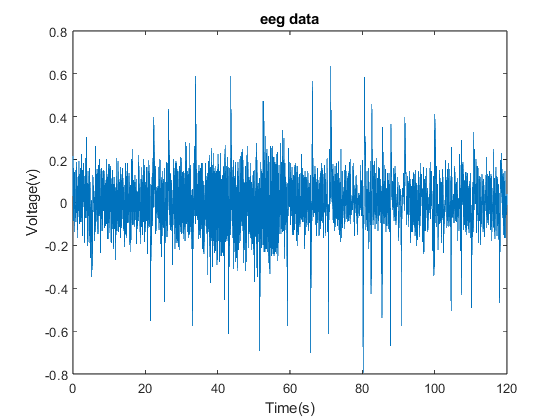

data_test_eeg1=trial2.eeg1;
data_test_emg1=trial2.emg7;
data_test_eeg1=data_test_eeg1*(3.3/4096);
data_test_emg1=data_test_emg1*(3.3/4096);
Fr_data=length(data_test_emg1)/120;
ti_data=1/Fr_data;
T_data1=[0:1:(length(data_test_eeg1)-1)]*ti_data;

data_test_eeg1_fft=fft(data_test_eeg1);
data_test_eeg1_fft(1)=0;
data_test_eeg1=ifft(data_test_eeg1_fft);
plot(T_data1,data_test_eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

data_test_emg1_fft=fft(data_test_emg1);
data_test_emg1_fft(1)=0;
data_test_emg1=ifft(data_test_emg1_fft)

data_test_emg1 =    -0.0742
   -0.0766
   -0.0863
   -0.0774
   -0.0742
   -0.0790
   -0.0806
   -0.0766
   -0.0814
   -0.0847


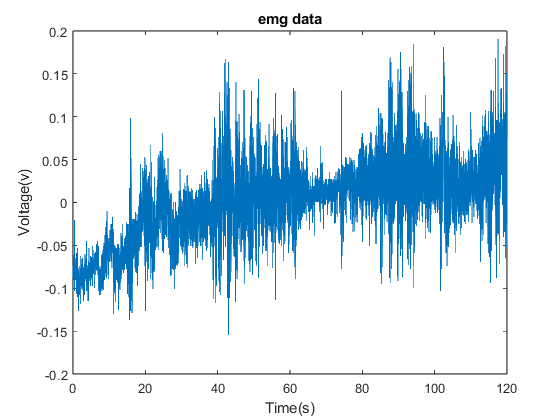

plot(T_data1,data_test_emg1)

xlim('auto')
ylim('auto')
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

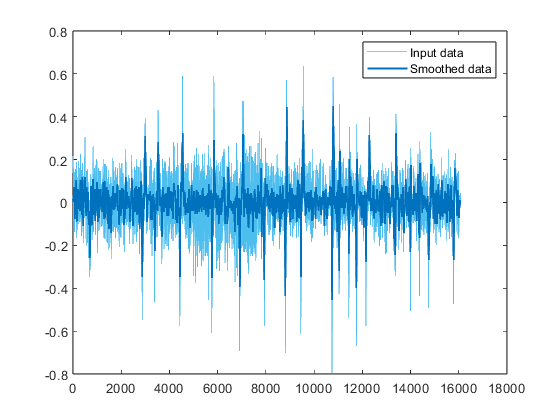

% Smooth input data
smoothedData_1 = smoothdata(data_test_eeg1,"movmean","SmoothingFactor",0.5);

% Display results
clf
plot(data_test_eeg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

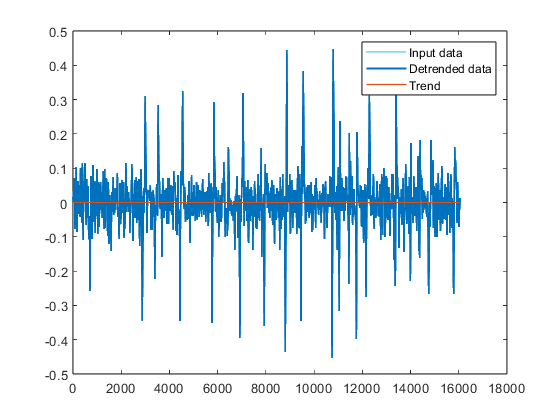

% Remove trend from data
smoothedData_1 = detrend(smoothedData_1);

% Display results
clf
plot(smoothedData_1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData_1-smoothedData_1,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

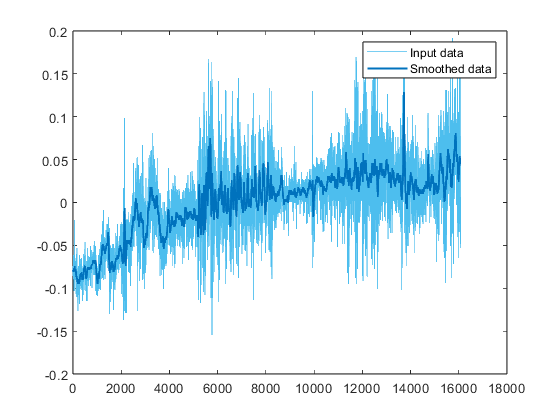

% Smooth input data
smoothedData_5 = smoothdata(data_test_emg1,"movmean","SmoothingFactor",0.3);

% Display results
clf
plot(data_test_emg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_5,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

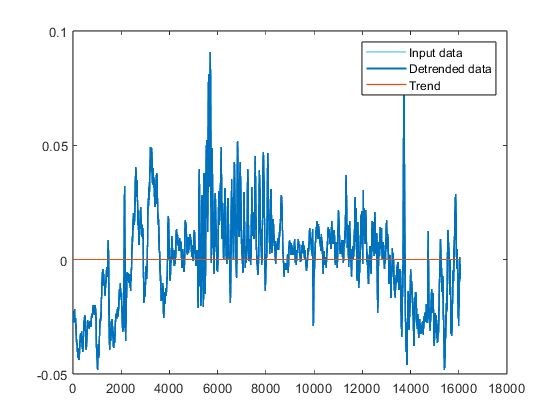

% Remove trend from data
smoothedData_5 = detrend(smoothedData_5);

% Display results
clf
plot(smoothedData_5,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_5,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData_5-smoothedData_5,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

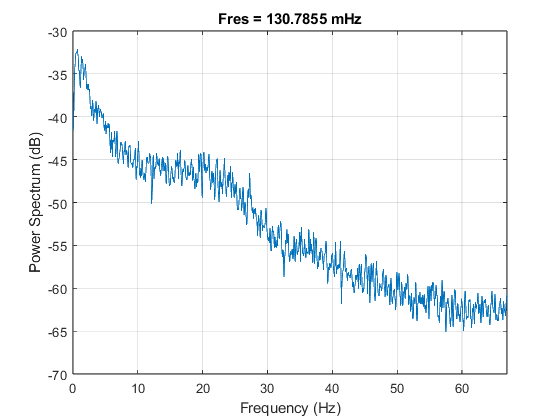

pspectrum(data_test_eeg1,Fr_data,"power")

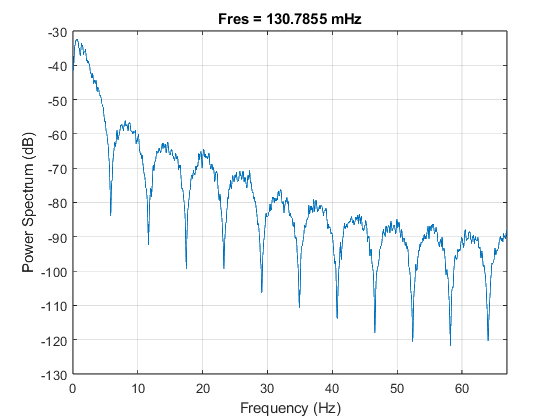

pspectrum(smoothedData_1,Fr_data,"power")

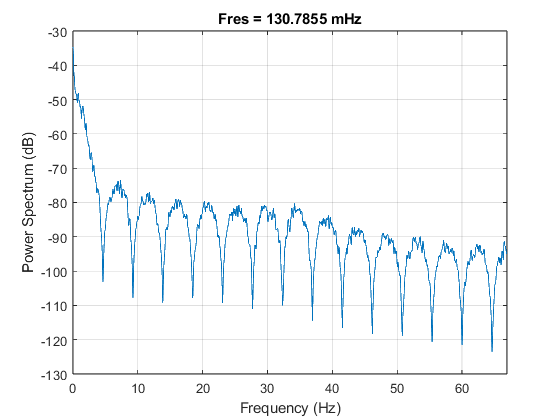

pspectrum(smoothedData_5,Fr_data,"power")

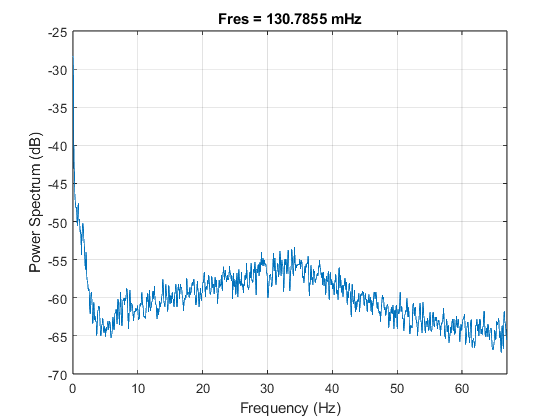

pspectrum(data_test_emg1,Fr_data,"power")

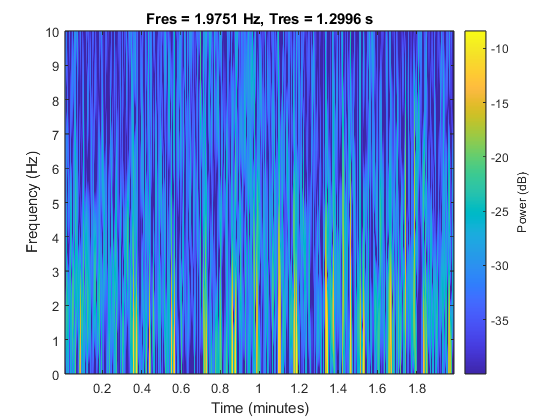

pspectrum(data_test_eeg1*1,Fr_data,"spectrogram",'MinThreshold',-40,"TimeResolution",1.3,"FrequencyLimits",[0,10],"OverlapPercent",90)

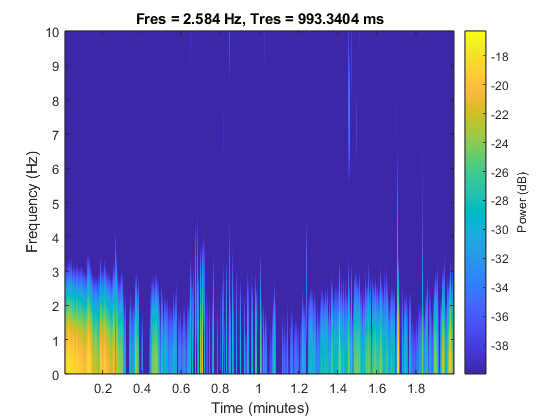

pspectrum(data_test_emg1*1,Fr_data,"spectrogram",'MinThreshold',-40,"TimeResolution",1,"FrequencyLimits",[0,10],"OverlapPercent",90)

[eeg1corr,lagscorr1]=crosscorr(data_test_eeg1*10,data_test_emg1*10);

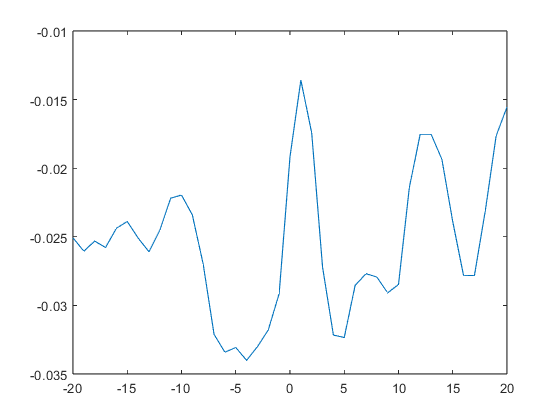

plot(lagscorr1,eeg1corr)

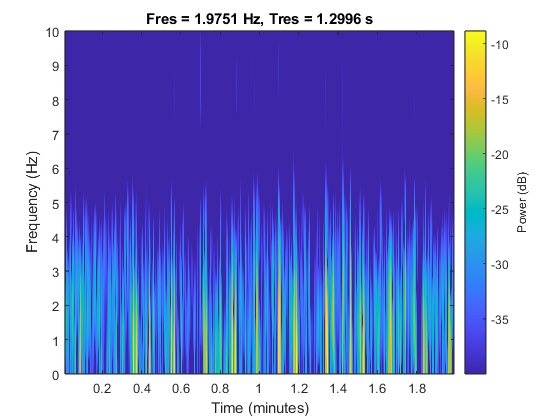

pspectrum(smoothedData_1*1,Fr_data,"spectrogram",'MinThreshold',-40,"TimeResolution",1.3,"FrequencyLimits",[0,10],"OverlapPercent",90)

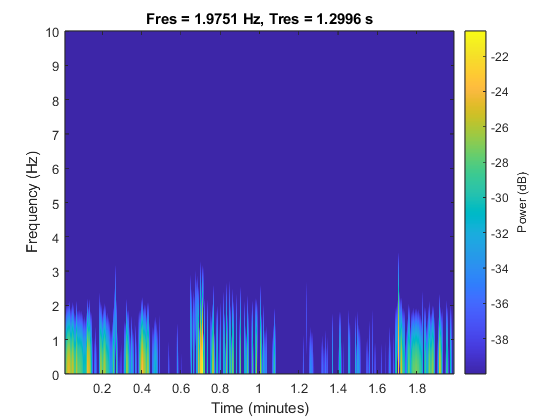

pspectrum(smoothedData_5*1,Fr_data,"spectrogram",'MinThreshold',-40,"TimeResolution",1.3,"FrequencyLimits",[0,10],"OverlapPercent",90)

note that the trial 2 coducted is discarded due to conection issues

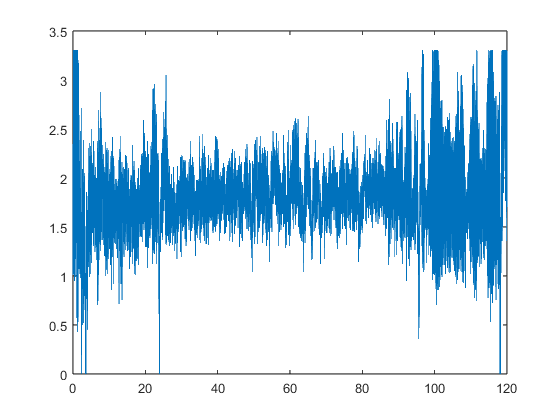

data_test2_eeg1=trial3.VarName1;
data_test2_emg1=trial3.VarName7;
data_test2_eeg1=data_test2_eeg1*(3.3/4096);
data_test2_emg1=data_test2_emg1*(3.3/4096);
Fr_data2=length(data_test2_emg1)/120;
ti_data2=1/Fr_data2;
T_data2=[0:1:(length(data_test2_eeg1)-1)]*ti_data2;
plot(T_data2,data_test2_eeg1)

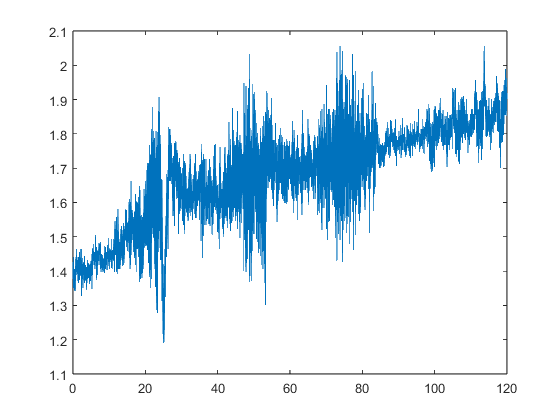

plot(T_data2,data_test2_emg1)

data_test2_eeg1_fft=fft(data_test2_eeg1);
data_test2_eeg1_fft(1)=0;
data_test2_eeg1=ifft(data_test2_eeg1_fft)

data_test2_eeg1 =    -0.8157
   -0.4355
    0.0044
    0.5160
    0.8222
    0.5346
   -0.1067
   -0.7561
   -0.5539
    0.0624


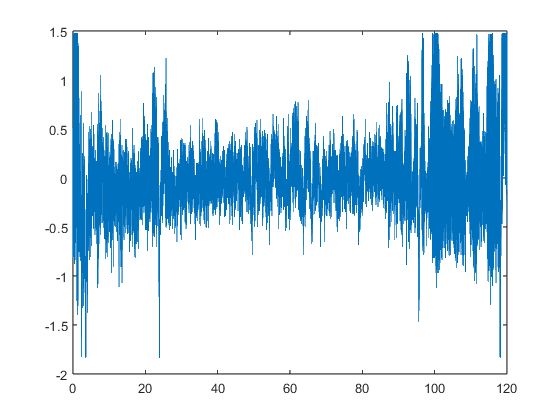

plot(T_data2,data_test2_eeg1);

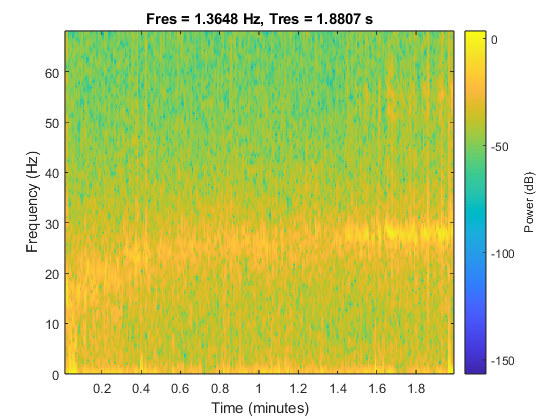

pspectrum(data_test2_eeg1,Fr_data2,"spectrogram");

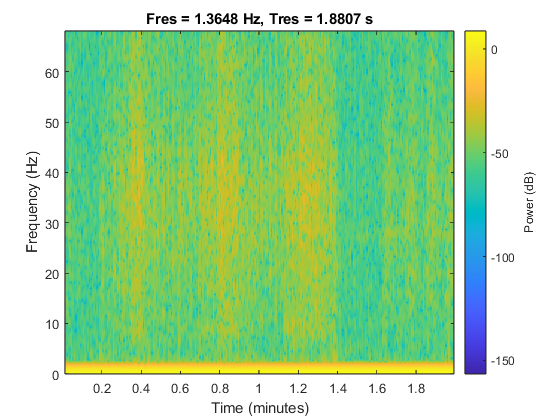

pspectrum(data_test2_emg1,Fr_data2,"spectrogram");

data_test3_eeg1=trial4.VarName1;
data_test3_emg1=trial4.VarName7;
data_test3_eeg1=data_test3_eeg1*(3.3/4096);
data_test3_emg1=data_test3_emg1*(3.3/4096);
Fr_data3=length(data_test3_emg1)/120;
ti_data3=1/Fr_data3;
T_data3=[0:1:(length(data_test3_eeg1)-1)]*ti_data3;
data_test3_eeg1_fft=fft(data_test3_eeg1);
data_test3_eeg1_fft(1)=0;
data_test3_eeg1=ifft(data_test3_eeg1_fft)

data_test3_eeg1 =     0.2294
    0.2697
    0.2286
    0.2181
    0.2294
    0.2721
    0.2673
    0.2834
    0.2463
    0.2834


data_test3_emg1_fft=fft(data_test3_emg1);
data_test3_emg1_fft(1)=0;
data_test3_emg1=ifft(data_test3_emg1_fft)

data_test3_emg1 =    -0.4617
   -0.5052
   -0.4964
   -0.5068
   -0.4891
   -0.5157
   -0.5044
   -0.5350
   -0.5391
   -0.4923


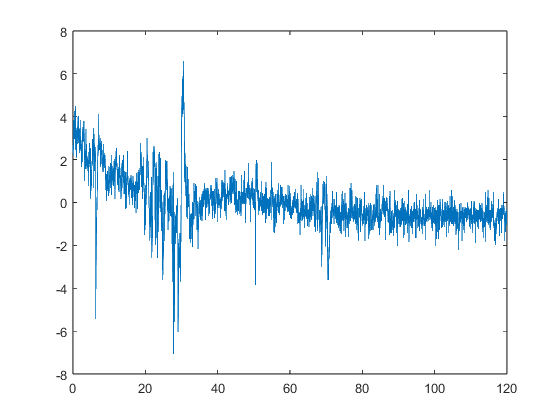

plot(T_data3,data_test3_eeg1*10)

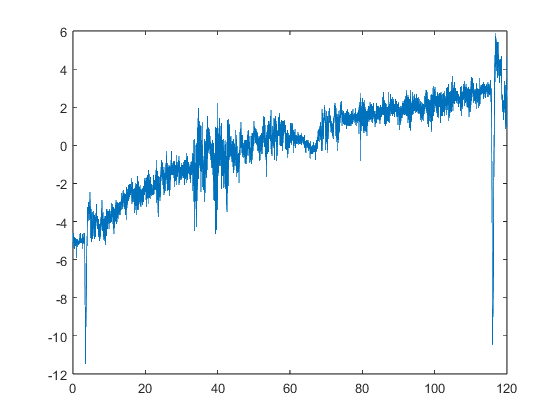

plot(T_data3,data_test3_emg1*10)

overlap=0

overlap = 0

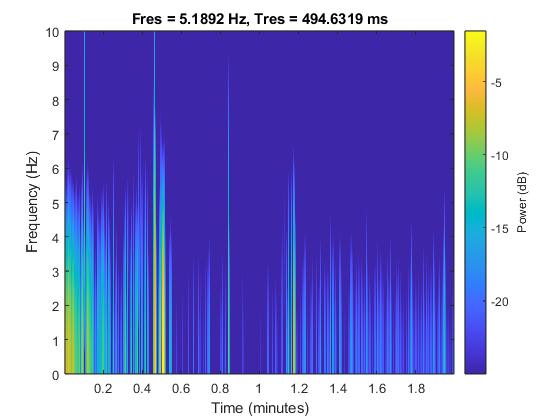

pspectrum(data_test3_eeg1*1,Fr_data3,"spectrogram",'MinThreshold',-25,"TimeResolution",0.5,"FrequencyLimits",[0,10],"OverlapPercent",90)

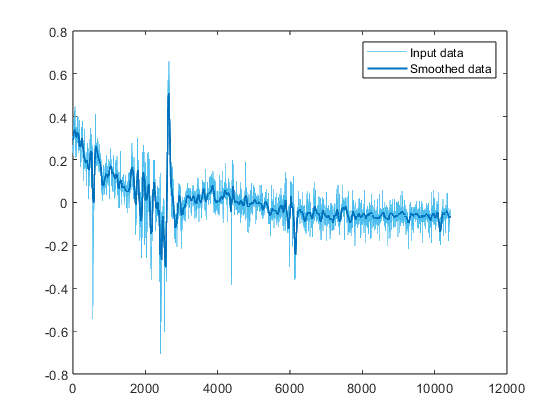

% Smooth input data
smoothedData_6 = smoothdata(data_test3_eeg1,"movmean","SmoothingFactor",0.25);

% Display results
clf
plot(data_test3_eeg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_6,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

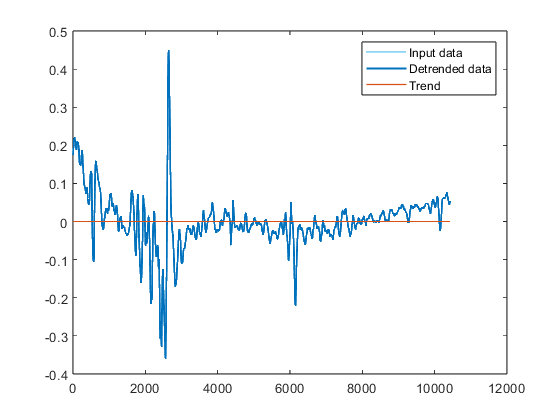

% Remove trend from data
smoothedData_6 = detrend(smoothedData_6);

% Display results
clf
plot(smoothedData_6,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_6,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData_6-smoothedData_6,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

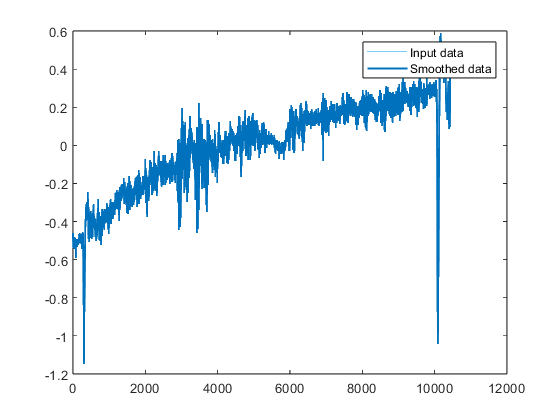

% Smooth input data
smoothedData_7 = smoothdata(data_test3_emg1,"rlowess","SmoothingFactor",0.01);

% Display results
clf
plot(data_test3_emg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_7,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

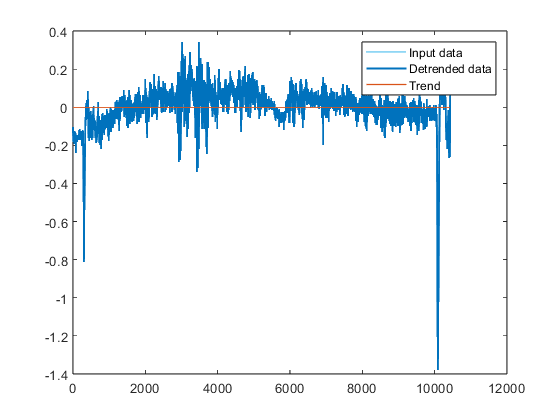

% Remove trend from data
smoothedData_7 = detrend(smoothedData_7);

% Display results
clf
plot(smoothedData_7,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData_7,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData_7-smoothedData_7,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

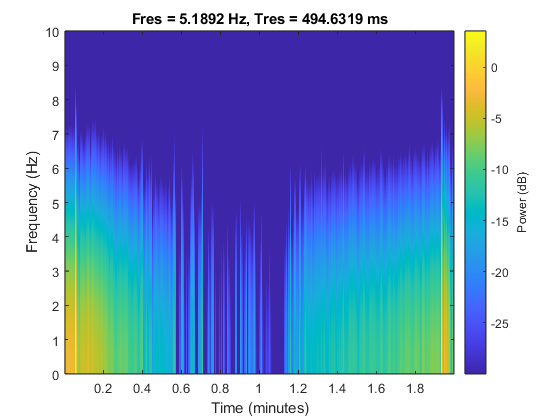

pspectrum(data_test3_emg1*1,Fr_data3,"spectrogram",'MinThreshold',-30,"TimeResolution",0.5,"OverlapPercent",80,"FrequencyLimits",[0,10])

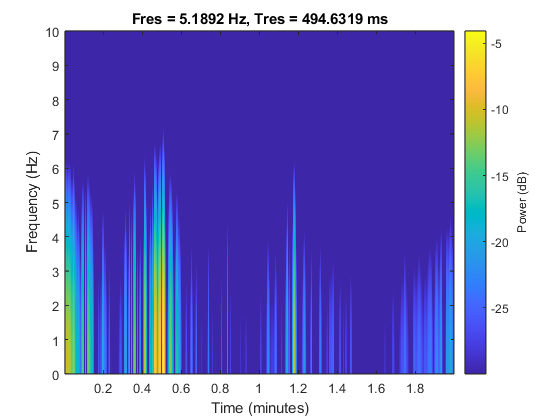

pspectrum(smoothedData_6*1,Fr_data3,"spectrogram",'MinThreshold',-30,"TimeResolution",0.5,"OverlapPercent",80,"FrequencyLimits",[0,10])

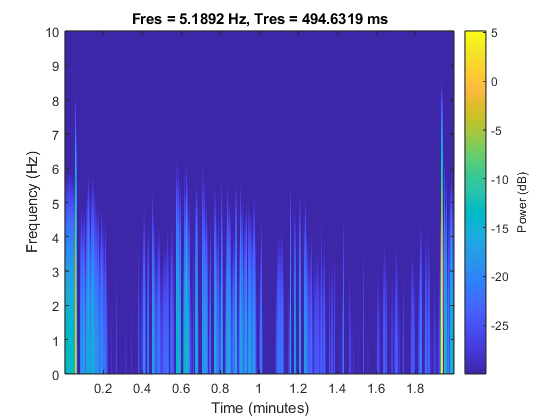

pspectrum(smoothedData_7*1,Fr_data3,"spectrogram",'MinThreshold',-30,"TimeResolution",0.5,"OverlapPercent",80,"FrequencyLimits",[0,10])

[eeg3corr,lagscorr3]=crosscorr(data_test3_eeg1*10,data_test3_emg1*10);

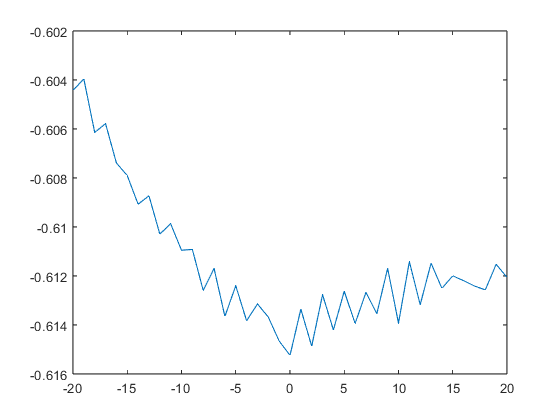

plot(lagscorr3,eeg3corr)

outeeg_and_emg1=[data_test_eeg1,data_test_emg1];
outeeg_and_emg1_smooth=[smoothedData_1,smoothedData_5];

outeeg_and_emg3=[data_test3_eeg1,data_test3_emg1];


outeeg_and_emg3_smooth=[smoothedData_6,smoothedData_7];

